# Plot substorm statistics

load("G:\My Drive\Research\Projects\Paper 3\Data\table_of_substorms_full.mat");

% Filter the table
T = T1(T1.AE>0,:);

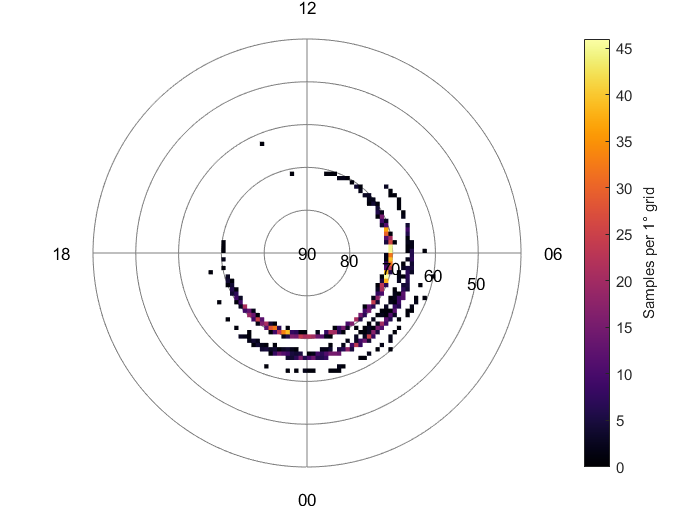

% Plot the statistics
figure;
set(gca,'XColor', 'none','YColor','none');
h=histogram2Polar(deg2rad(T.MLT.*360./24),90-(T.MLAT),1,'RTicks',90-[90,80,70,60,50],'RLim',90-[90,40]);
h.RAxisLabels(1).String='90';
h.RAxisLabels(2).String='80';
h.RAxisLabels(3).String='70';
h.RAxisLabels(4).String='60';
h.RAxisLabels(5).String='50';
h.ThetaAxisLabels(1).String='00';
h.ThetaAxisLabels(2).String='06';
h.ThetaAxisLabels(3).String='12';
h.ThetaAxisLabels(4).String='18';
h.ThetaZeroLocation='bottom';
h.Colorbar.Label.String='Samples per 1° grid';
set(gca,'ColorScale','linear');
colormap(inferno);

## Complete superMag Database

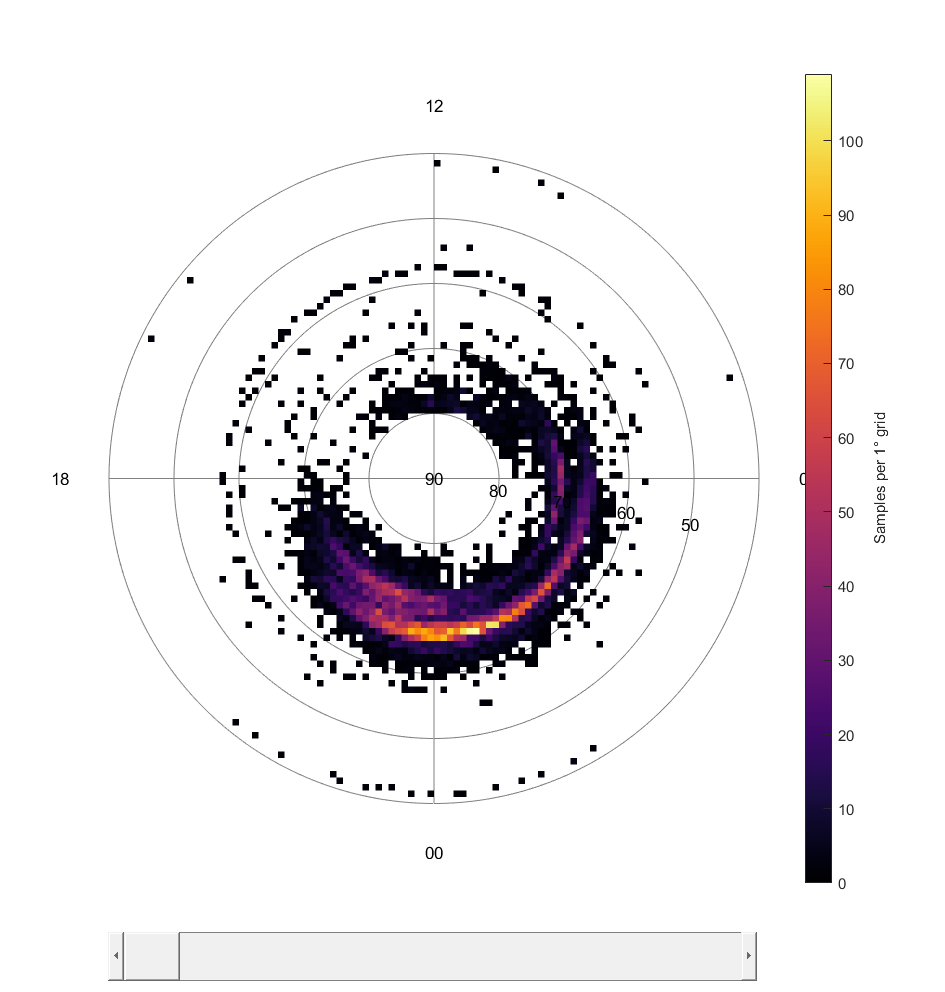

% Plot statistics
AE_min=0;
f = figure;
resize_figure(f,210,200);
ax = axes('Parent',f);
set(ax,'XColor', 'none','YColor','none');
h=plot_substorm_statistics(AE_min,superMag);
h=histogram2Polar(deg2rad(superMag.mlt(filterIndx)*360./24),90-(superMag.mlat(filterIndx)),1,'RTicks',90-[90,80,70,60,50],'RLim',90-[90,40]);
h.RAxisLabels(1).String='90';
h.RAxisLabels(2).String='80';
h.RAxisLabels(3).String='70';
h.RAxisLabels(4).String='60';
h.RAxisLabels(5).String='50';
h.ThetaAxisLabels(1).String='00';
h.ThetaAxisLabels(2).String='06';
h.ThetaAxisLabels(3).String='12';
h.ThetaAxisLabels(4).String='18';
h.ThetaZeroLocation='bottom';
h.Colorbar.Label.String='Samples per 1° grid';
set(gca,'ColorScale','linear');
pos=get(ax,'position');
Newpos=[pos(1) pos(2)-0.1 pos(3) 0.05];
p=uicontrol('style','slider',...
    'units','normalized','position',Newpos,...
    'callback',{@plotCreator,superMag,Newpos},'min',0,'max',1400);

colormap(inferno);

function plotCreator(ObjH,EventData,superMag,Newpos)
    plot_substorm_statistics_1(ObjH.Value,superMag);
    colormap(inferno);
    label()
end

function h=plot_substorm_statistics(AE,superMag)
filterIndx = superMag.AE>AE & superMag.AE<1400;
h=histogram2Polar(deg2rad(superMag.mlt(filterIndx)*360./24),90-(superMag.mlat(filterIndx)),1,'RTicks',90-[90,80,70,60,50],'RLim',90-[90,40]);
h.RAxisLabels(1).String='90';
h.RAxisLabels(2).String='80';
h.RAxisLabels(3).String='70';
h.RAxisLabels(4).String='60';
h.RAxisLabels(5).String='50';
h.ThetaAxisLabels(1).String='00';
h.ThetaAxisLabels(2).String='06';
h.ThetaAxisLabels(3).String='12';
h.ThetaAxisLabels(4).String='18';
h.ThetaZeroLocation='bottom';
h.Colorbar.Label.String='Samples per 1° grid';
set(gca,'ColorScale','linear');
end

function h=plot_substorm_statistics_1(AE,superMag)
filterIndx = superMag.AE>AE & superMag.AE<1400;
h=histogram2Polar(deg2rad(superMag.mlt(filterIndx)*360./24),90-(superMag.mlat(filterIndx)),1,'RTicks',90-[90,80,70,60,50],'RLim',90-[90,40]);
h.RAxisLabels(1).String=' ';
h.RAxisLabels(2).String=' ';
h.RAxisLabels(3).String=' ';
h.RAxisLabels(4).String=' ';
h.RAxisLabels(5).String=' ';
h.ThetaAxisLabels(1).String=' ';
h.ThetaAxisLabels(2).String=' ';
h.ThetaAxisLabels(3).String=' ';
h.ThetaAxisLabels(4).String=' ';
h.ThetaZeroLocation='bottom';
h.Colorbar.Label.String=' ';
set(gca,'ColorScale','linear');
end